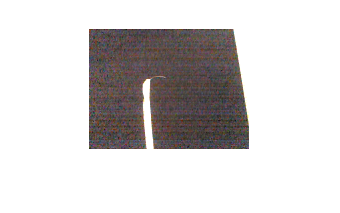

%Dr. Sankalp Bhan
%ESE 448

%References:
% #1. Digital Image Processing with Matlab: Gonzalez, Woods, Eddins 
% #2. https://www.mathworks.com/help/images/hough-transform.html#buh9ylp-26

% load up some image data
load('RSdata.mat');


%% Load an Image
figure;
idx = 28;
R = rt_ColorR.signals.values(:,:,idx);
G = rt_ColorG.signals.values(:,:,idx);
B = rt_ColorB.signals.values(:,:,idx);
picture = cat(3,R,G,B);
greyImage = rgb2gray(picture);

imshow(picture)


% apply an intensity transformation (to be discussed later)
greyImage = imcomplement(greyImage); 

# Spatial Filtering

Take the spatial filtering center of and apply an I/O operation to pixels in the neighborhood

For example, we may take a center point (x,y) and perform an operation that involves the neighboring about (x,y). The output at (x,y) is a function of the neighboring of the input (x,y)


$$s(x,y) = f(x,y, N(x,y))$$


In the special case that the filtering is linear, we can apply a linear spatial filter where the operation will become the convolution or the correlation. 


$$w(x,y) * f(x,y) = \sum_{s=-a}^{a}\sum_{t=-b}^{b}w(s,t) f(x+s, y+
t)$$



$$w(x,y) \star f(x,y) = \sum_{s=-a}^{a}\sum_{t=-b}^{b}w(s,t) f(x-s, y-t)$$


The formulas obfuscate the simplicity. Consider 9 pixels in an image, the 8 points that surround a center pixel.

% (x-1,y-1)  (x-1,y )   (x-1,y+1)
% (x,y-)     (x,y)      (x,y+1) 
% (x+1,y-1)  (x+1,y)    (x+1,y+1)

to each point we ascribe a mask function with weights $w$

% w(-1,-1)  w(-1,0)    w(-1,+1)
% w(0,-1)   w(0,0)     w(0,+1) 
% w(+1,-1)  w(1,0)     w(+1,+1)

As an example, consider the 3x3 mask and use it to filter an image. 

We will set this image to blur!

% 1/9  1/9  1/9
% 1/9  1/9  1/9  = M
% 1/9  1/9  1/9

N=3

N = 3

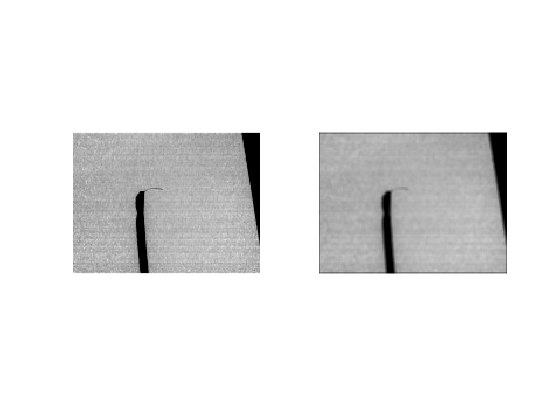

w = ones(N)/N^2;
filtered_image = imfilter(greyImage,w);
figure
subplot(1,2,1); imshow(greyImage);

subplot(1,2,2); imshow(filtered_image)

# Intensity Transformation

An intensiry transformation is mapping a new image from an old one. The intensity transformation can be written as


$$s(x,y)=T{r}(x,y)$$


where $r$ is is the original intensity and s is the tranformed intensity.

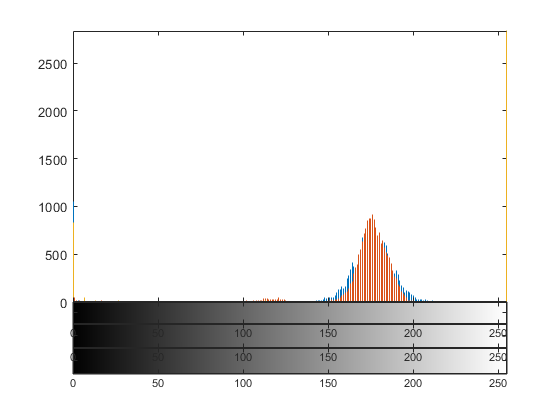

adjGreyImage = imadjust(filtered_image,[0 0.15],[0,1]);

figure
imhist(greyImage);
hold on;
imhist(filtered_image)
imhist(adjGreyImage)

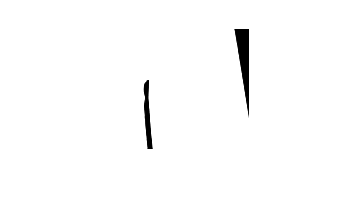



figure;
imshow(adjGreyImage)

# Line Detectors

A line detector can detect lines that are a length or width of a certain amount of pixels.  

The detector should have weights which sum to zero. The detector amplifies pixels that match the mask patterns.

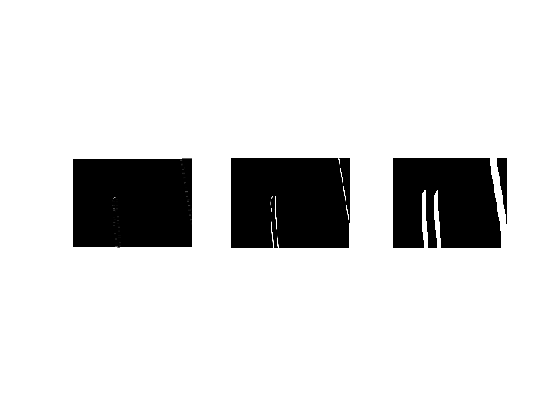

% detect horizontal lines
w_h = [-1 -1 -1 ;...
      2  2  2  ;...
     -1 -1 -1 ] ;
w_v = [-1 2 -1 ; -1 2 -1 ; -1 2 -1];
N = 15;
w_v_15 = [-N*ones(N+2,1) 2*ones(N+2,N)  -N*ones(N+2,1)];
h = imfilter(adjGreyImage , w_h) ;
v = imfilter(adjGreyImage, w_v);
v_15 = imfilter(adjGreyImage, w_v_15);


figure
subplot(131)
imshow ( h )
subplot(132)
imshow(v);
subplot(133)
imshow(v_15)

# Edge Detectors

A simple method to find the lines in an image is an edge detector. An edge detector simply uses the differences in pixels to find the edges.

The three most common types of edge detectors are the Sobel detector, the Prewitt detector, and the Canny edge detector.

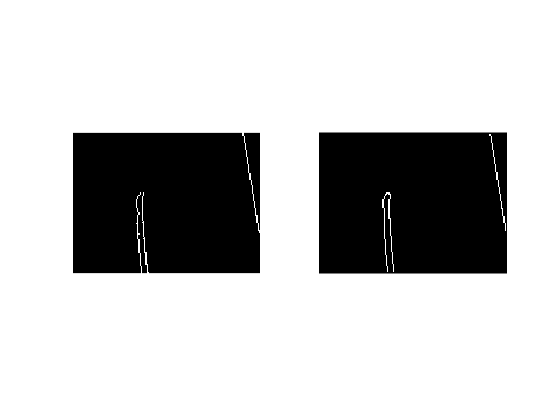

figure
sob_thresh = [0.3]; % try 0.3
can_thres = [1/2, 7/8]; % try [1/2, 7/8] with lo/hi
can_sigma = [];

%% Grab the edges
v_151 = edge(adjGreyImage,'sobel','vertical', sob_thresh);
v_152 = edge(adjGreyImage,'canny',can_thres);
subplot(1,2,1); imshow(v_151); subplot(1,2,2);imshow(v_152)

# Hough Transform

The hough transform can be used to link the pixels in edges, especially if the edges are discontinous. Given a binary image, we want to find subsets of points that lie on a straight line.

Given a point, finding all lines connecting to the one under consideration gives a point (x,y). Represent the line by its normal form 


$$x\cos \theta +y \sin \theta=\rho$$


Considering a $p-\theta$ space, the range of expected values for these parameters confines teh ranges of parameter values. The array of values in p-\theta place is the Hough transform matrix.

In matlab, hough peaks find hough transform matrix. The function houghlines function uses this result.

 Compute the Hough transform of the binary image returned by `edge`.

[H,theta,rho] = hough(v_15);

Display the transform, `H`, returned by the `hough` function.

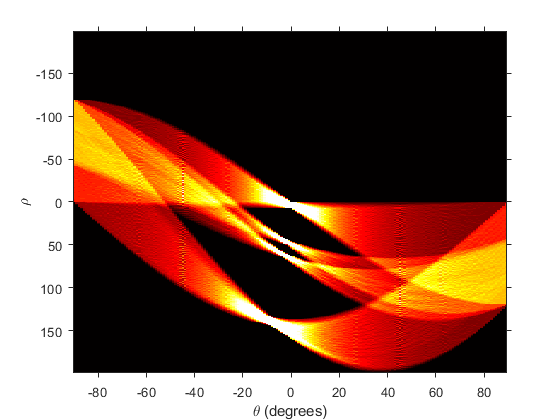

figure
imshow(imadjust(rescale(H)),[],...
       'XData',theta,...
       'YData',rho,...
       'InitialMagnification','fit');
xlabel('\theta (degrees)')
ylabel('\rho')
axis on
axis normal 
hold on
colormap(gca,hot)

Find the peaks in the Hough transform matrix, `H`, using the `houghpeaks` function.

P = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));

Superimpose a plot on the image of the transform that identifies the peaks.

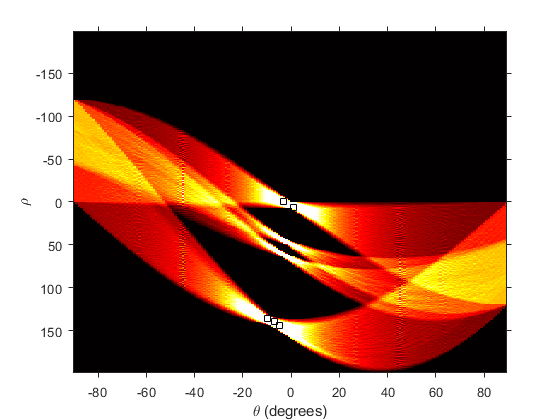

x = theta(P(:,2));
y = rho(P(:,1));
plot(x,y,'s','color','black');

Find lines in the image using the `houghlines` function. 

lines = houghlines(v_15,theta,rho,P,'FillGap',5,'MinLength',7);

Create a plot that displays the original image with the lines superimposed on it.

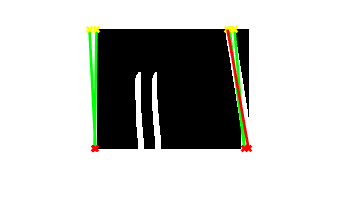

figure, imshow(v_15), hold on
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end
% highlight the longest line segment
plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','red');